# パラメータ化拡張GFT

2024年4月29日

村松正吾，内藤翼（新潟大学）

#### 参考文献:

- H. Kitamura, H. Yasuda, Y. Tanaka and S. Muramatsu, "Realization of DiGraph Filters Via Augmented GFT," 2023 IEEE International Conference on Image Processing (ICIP), Kuala Lumpur, Malaysia, 2023, pp. 2885-2889, doi: 10.1109/ICIP49359.2023.10222618.

- Abstract: This study proposes a filtering method for directed graph (digraph) signals. In order to realize digraph filtering, a novel graph Fourier transform (GFT), – Augmented GFT (AuGFT) –, is proposed by defining an Hermitian adjacency matrix. Although there has been the same method to give the adjacency matrix of digraphs, this study defines a novel digraph Laplacian. The existing digraph Laplacian does not give the graph signal variation considering the edge directions, while the novel one does. This paper introduces three important ideas. The first is the definition of a novel degree matrix to give the novel digraph Laplacian. The second is to decompose the symmetric and skew-symmetric components of the novel digraph Laplacian independently into their spectral components. The third is, based on the decomposition, to augment the conventional GFT for digraphs as an invertible real-valued dictionary. The new GFT is shown to provide a practical form of real-valued digraph filtering. The significance of the proposed method is verified through simulations of signal filtering on digraphs.

- URL: [https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892](https://ieeexplore.ieee.org/stamp/stamp.jsp?tp=&arnumber=10222618&isnumber=10221892)

**謝辞：**

- 本研究は[科研費21H04596](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-21H04596/)および[科研費22H00512](https://kaken.nii.ac.jp/ja/grant/KAKENHI-PROJECT-22H09512/)助成による。

## 各種設定

isDiGraph = true; % 有向グラフとして解析

if ~exist('./gspbox','dir')
    setup
else
    addpath('gspbox')
end
gsp_start

GSPBox version 0.7.5. Copyright 2013-2015 LTS2-EPFL,
by Nathanael Perraudin, Johan Paratte, David Shuman and Vassilis Kalofolias


RESULTS_DIR = "../results/";
FIGEXT = ".png";

## 有向グラフの隣接行列 $\mathbf{A}$ の生成

有向グラフ $\mathcal{G}$ の定義

s = [1 1 2 2 3 3 4 4 4 5];
t = [2 3 4 5 6 7 8 9 10 4];
G = digraph(s,t)

G =   digraph のプロパティ:

    Edges: [10×1 table]
    Nodes: [10×0 table]


有向非巡回性の確認

isdag(G)

ans = logical
   1


有向グラフ $\mathcal{G}$ のエッジ $\mathcal{E}$

G.Edges

ans = 10×1 table
    EndNodes
    ________

    1     2 
    1     3 
    2     4 
    2     5 
    3     6 
    3     7 
    4     8 
    4     9 
    4    10 
    5     4 


有向グラフ $\mathcal{G}$ のノード $\mathcal{V}$ 

G.Nodes


ans =

  10×0 の空の table



## 有向グラフ $\mathcal{G}$の描画

A = full(adjacency(G,'weighted'))

A =      0     1     1     0     0     0     0     0     0     0
     0     0     0     1     1     0     0     0     0     0
     0     0     0     0     0     1     1     0     0     0
     0     0     0     0     0     0     0     1     1     1
     0     0     0     1     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0
     0     0     0     0     0     0     0     0     0     0


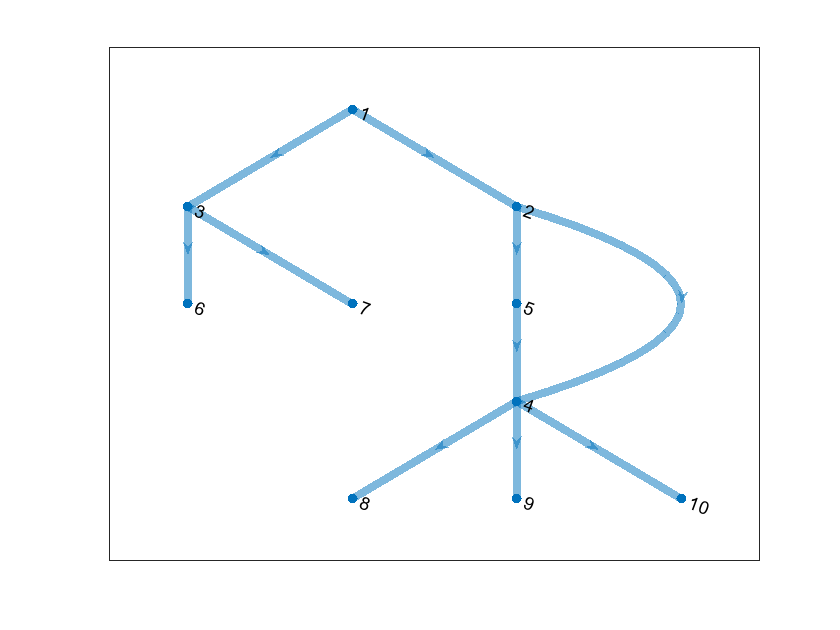

figure
h = plot(G,'LineWidth',4,'Layout','layered');

if ~isDiGraph
    if isa(A,'digraph') || isa(A,'graph')
        A = adjacency(A);
    end
    A = (A+A.')/2;
end
[U,Q,C,D,L,Lmd,Sgm] = fcn_digraphops(A)

U =     0.2531    0.0136   -0.0000   -0.0000   -0.0000   -0.5340    0.6691    0.0443   -0.4458    0.0475
    0.1507   -0.1399   -0.0000    0.0000   -0.0000   -0.4741   -0.0484   -0.6651    0.4861   -0.2281
    0.3839    0.1673   -0.0000    0.0000   -0.0000   -0.0710    0.2010    0.5793    0.6659   -0.0141
    0.1405   -0.2829         0    0.0000   -0.0000   -0.0788   -0.0996   -0.0864    0.1066    0.9302
    0.1379   -0.2101   -0.0000    0.0000   -0.0000   -0.5416   -0.6489    0.3884   -0.2294   -0.1378
    0.5502    0.2798   -0.5293    0.2619   -0.3889    0.1805   -0.1695   -0.1730   -0.1665    0.0022
    0.5502    0.2798    0.5293   -0.2619    0.3889    0.1805   -0.1695   -0.1730   -0.1665    0.0022
    0.2014   -0.4731   -0.4863   -0.6044    0.2548    0.2003    0.0840    0.0258   -0.0267   -0.1429
    0.2014   -0.4731    0.4493   -0.0946   -0.6752    0.2003    0.0840    0.0258   -0.0267   -0.1429
    0.2014   -0.4731    0.0370    0.6990    0.4204    0.2003    0.0840    0.0258   -0.0

Q =     0.3505    0.0234    0.5908    0.0508   -0.4146   -0.0124
    0.0426   -0.6365    0.0127   -0.1472   -0.0226    0.7555
    0.0145   -0.2172    0.0777   -0.9035    0.0108   -0.3608
   -0.8248    0.2759    0.3280   -0.1490   -0.2398    0.2372
   -0.3747   -0.3562    0.0010    0.1773    0.5444   -0.2281
   -0.0892   -0.0060   -0.5080   -0.0437   -0.3790   -0.0113
   -0.0892   -0.0060   -0.5080   -0.0437   -0.3790   -0.0113
    0.1133    0.3387   -0.0838   -0.1844    0.2492    0.2519
    0.1133    0.3387   -0.0838   -0.1844    0.2492    0.2519
    0.1133    0.3387   -0.0838   -0.1844    0.2492    0.2519


C =    0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.5000 + 0.5000i   0.5000 + 0.5000i
   0.0000 + 0.0000i   0.5000 - 0.5000i   0.0000 + 0.0000i   0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i   

D =     1.4142         0         0         0         0         0         0         0         0         0
         0    2.1213         0         0         0         0         0         0         0         0
         0         0    2.1213         0         0         0         0         0         0         0
         0         0         0    3.5355         0         0         0         0         0         0
         0         0         0         0    1.4142         0         0         0         0         0
         0         0         0         0         0    0.7071         0         0         0         0
         0         0         0         0         0         0    0.7071         0         0         0
         0         0         0         0         0         0         0    0.7071         0         0
         0         0         0         0         0         0         0         0    0.7071         0
         0         0         0         0         0         0         0         0       

L =    1.4142 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 + 0.5000i   2.1213 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
  -0.5000 + 0.5000i   0.0000 + 0.0000i   2.1213 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   3.5355 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i   0.0000 + 0.0000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i  -0.5000 - 0.5000i
   0.0000 + 0.0000i  -0.5000 + 0.5000i   0.0000 + 0.0000i  -0.5000 - 0.5000i   1.4142 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i   0.0000 + 0.0000i
   0.0000 + 0.0000i   0.0000 + 0.0000i  -

Lmd =     0.3583         0         0         0         0         0         0         0         0         0
         0    0.4081         0         0         0         0         0         0         0         0
         0         0    0.7071         0         0         0         0         0         0         0
         0         0         0    0.7071         0         0         0         0         0         0
         0         0         0         0    0.7071         0         0         0         0         0
         0         0         0         0         0    0.9038         0         0         0         0
         0         0         0         0         0         0    1.3002         0         0         0
         0         0         0         0         0         0         0    2.3817         0         0
         0         0         0         0         0         0         0         0    2.7062         0
         0         0         0         0         0         0         0         0     

Sgm =          0    1.2177         0         0         0         0
   -1.2177         0         0         0         0         0
         0         0         0    0.8892         0         0
         0         0   -0.8892         0         0         0
         0         0         0         0         0    0.4760
         0         0         0         0   -0.4760         0


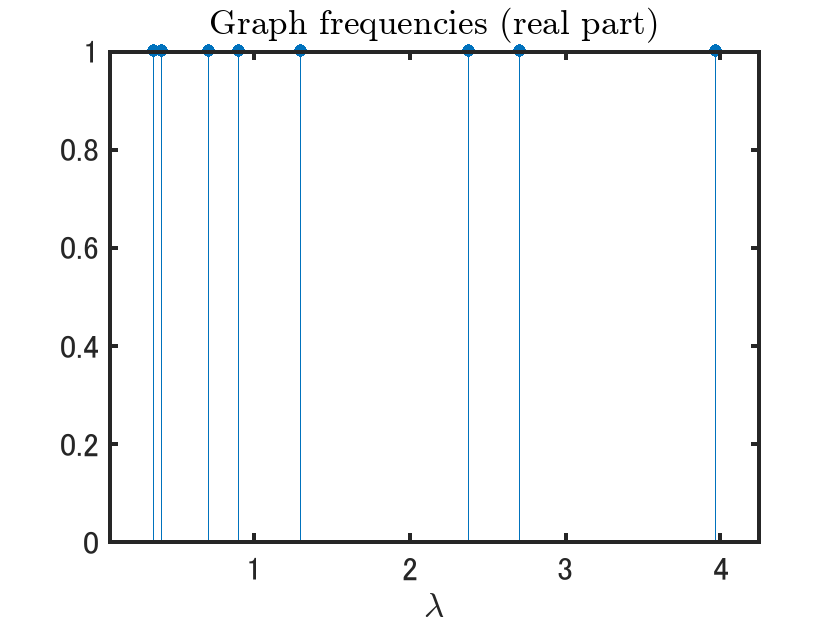

y = ones(1,size(Lmd,2));
stem(diag(Lmd),y,'filled')
title('Graph frequencies (real part)','Interpreter','latex')
xlabel('$\lambda$','Interpreter','latex')

ax = gca;
ax.LineWidth = 2;
ax.FontSize = 16;
exportgraphics(ax,RESULTS_DIR+"EigenValues_sym"+FIGEXT)

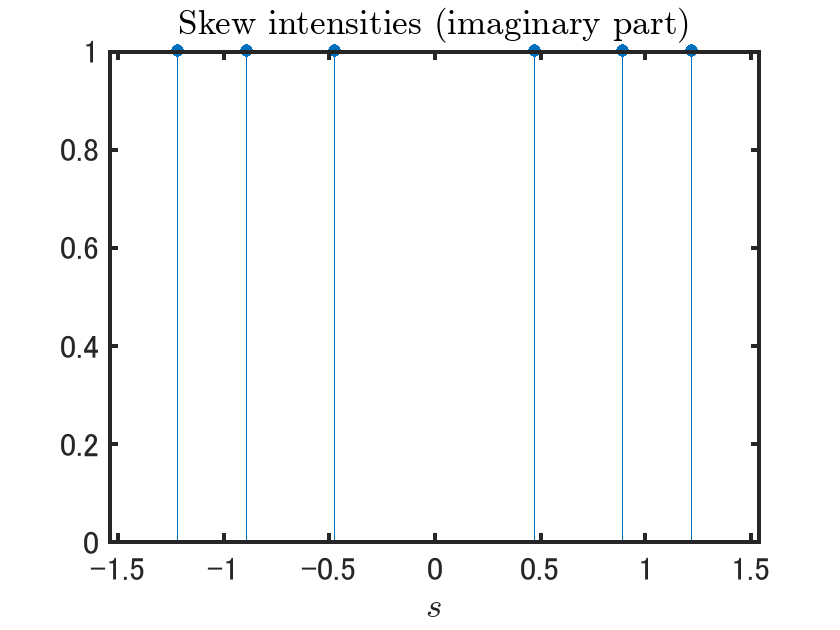

sgm = sort([diag(Sgm,1);diag(Sgm,-1)],'ascend');
idxg = find(sgm);
gma = sgm(idxg);
if ~isempty(gma)
    y = ones(1,length(gma));
    stem(gma,y,'filled')
    title('Skew intensities (imaginary part)','Interpreter','latex')
    xlabel('$s$','Interpreter','latex')

    ax = gca;
    ax.LineWidth = 2;
    ax.FontSize = 16;
    %exportgraphics(ax,RESULTS_DIR+"EigenValues_skw"+FIGEXT)
end

## $\;{\mathbf{u}}_{\lambda_k }$拡張GFT（対称成分）の基底ベクトル

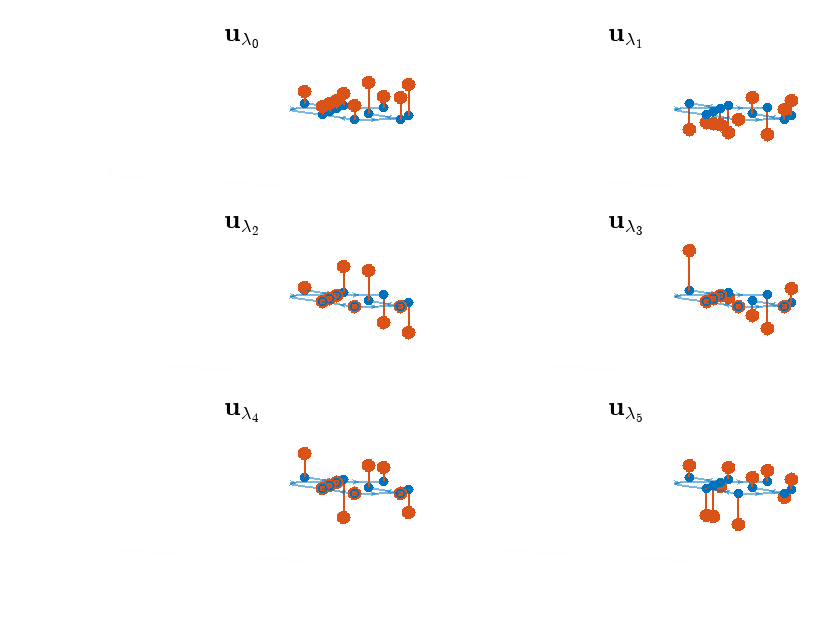

zscale = .8;
fontSize = 12; %36;
lineWidth = 1; %3;
arrowSize = 4; %12;
az = 200;
el = 20;
figure
tiledlayout(3,2)
for k = 0:5
    %figure
    nexttile
    %uk = U(:,k+1)*Lmd(k+1,k+1);
    uk = U(:,k+1);
    %
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,uk,'fill','LineWidth',lineWidth);
    %zlim(zscale*[-1 1])
    %axis off
    title("$\mathbf{u}_{\lambda_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"u"+num2str(k)+FIGEXT)
end

## $\;{\mathit{\mathbf{q}}}_{s_k }$拡張GFT（交代成分）の基底ベクトル

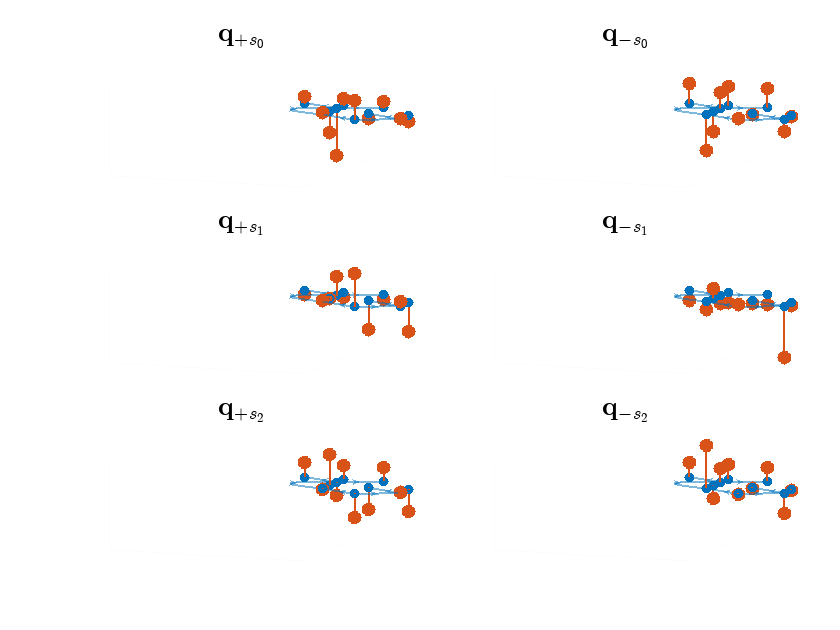

figure
tiledlayout(3,2)
for k = 0:min(5,length(gma)/2-1)
    %figure
    nexttile
    qkp = Q(:,2*k+1);
    % +sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,qkp,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{+s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"qp"+num2str(k)+FIGEXT)
    %
    %figure
    nexttile
    qkm = Q(:,2*k+2);
    % -sk
    p1 = plot(G,'LineWidth',lineWidth);
    p1.ArrowSize = arrowSize;
    p1.NodeLabel = {};
    hold on
    stem3(p1.XData,p1.YData,qkm,'fill','LineWidth',lineWidth);
    title("$\mathbf{q}_{-s_"+num2str(k)+"}$",'Interpreter','latex','FontSize',20)
    view(az,el)
    hold off
    ax = gca;
    ax.FontSize = fontSize;
    ax.ZLim = zscale*[-1 1];
    ax.Box = 'off';
    ax.XColor = .99*[1 1 1];
    ax.YColor = .99*[1 1 1];
    ax.ZColor = .99*[1 1 1];
    ax.XLim = [2 7];
    ax.YLim = [2 12];
    ax.Clipping = 'off';
    %exportgraphics(ax,RESULTS_DIR+"qm"+num2str(k)+FIGEXT)
end

## 
$$\;$$


## 変動の確認


$$\mathbf{L}=\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)$$



$$\underbrace{\left(\begin{array}{c}
y_{1}\\
y_{2}\\
y_{3}\\
y_{4}
\end{array}\right)}_{\mathbf{y}}=\underbrace{\left(\begin{array}{cccc}
d_{11} & -b_{12} & -b_{13} & -b_{14}\\
-\bar{b}_{12} & d_{22} & -b_{23} & -b_{24}\\
-\bar{b}_{13} & -\bar{b}_{23} & d_{33} & -b_{34}\\
-\bar{b}_{14} & -\bar{b}_{24} & -\bar{b}_{34} & d_{44}
\end{array}\right)}_{\mathbf{L}}\underbrace{\left(\begin{array}{c}
x_{1}\\
x_{2}\\
x_{3}\\
x_{4}
\end{array}\right)}_{\mathbf{x}}$$



$$d_{k,k}:=\sum_{\ell\in\mathcal{N}\backslash \{k\}} |c_{k,\ell}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  |c_{\ell,k}|=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}b_{\ell,k}}=\sum_{\ell\in\mathcal{N}\backslash \{k\}}  \sqrt{c_{k,\ell}\bar{c}_{k,\ell}}

$$


ただし， $\mathcal{N}:=\{1,2,\cdots,N\}$。


$$y_{k}=d_{k,k}x_k-\sum_{\ell=k+1}^{N} b_{k,\ell}x_\ell-\sum_{\ell=1}^{k-1} \bar{b}_{k,\ell}x_\ell$$



$$\Delta_{\mathbf{L}}(\mathbf{x})=\mathbf{x}^T\mathbf{L}\mathbf{x}=\sum_{k\in\mathcal{N}}\sum_{\ell=k+1}^N |b_{k,\ell}|\cdot|x_k-e^{-j\angle b_{k,\ell}} x_\ell|^2$$


行列計算

nDims = size(L,1);
x = randn(nDims,1);
xLx = x.'*L*x

xLx = 25.1280 + 0.0000i

累積加算

tv = 0;
for iRow = 1:nDims
    xk = x(iRow);
    for iCol = iRow+1:nDims
        ckl = C(iRow,iCol);
        xl = x(iCol);
        tv = tv + abs(ckl)*abs(xk-exp(1j*angle(ckl))*xl)^2;
    end
end
tv

tv = 25.1280

誤差評価

assert(abs(xLx - tv)<1e-6,'Invalid TV')

waterlevel = randn(nDims)

waterlevel =    -1.3499    0.6715    0.8884   -0.1022   -0.8637   -1.0891   -0.6156    1.4193   -1.1480    0.8404
    3.0349   -1.2075   -1.1471   -0.2414    0.0774    0.0326    0.7481    0.2916    0.1049   -0.8880
    0.7254    0.7172   -1.0689    0.3192   -1.2141    0.5525   -0.1924    0.1978    0.7223    0.1001
   -0.0631    1.6302   -0.8095    0.3129   -1.1135    1.1006    0.8886    1.5877    2.5855   -0.5445
    0.7147    0.4889   -2.9443   -0.8649   -0.0068    1.5442   -0.7648   -0.8045   -0.6669    0.3035
   -0.2050    1.0347    1.4384   -0.0301    1.5326    0.0859   -1.4023    0.6966    0.1873   -0.6003
   -0.1241    0.7269    0.3252   -0.1649   -0.7697   -1.4916   -1.4224    0.8351   -0.0825    0.4900
    1.4897   -0.3034   -0.7549    0.6277    0.3714   -0.7423    0.4882   -0.2437   -1.9330    0.7394
    1.4090    0.2939    1.3703    1.0933   -0.2256   -1.0616   -0.1774    0.2157   -0.4390    1.7119
    1.4172   -0.7873   -1.7115    1.1093    1.1174    2.3505   -0.1961   -1.16

## AuGFTによるフィルタ処理

パラメータ $\alpha$ を導入し一般化したAuGFT

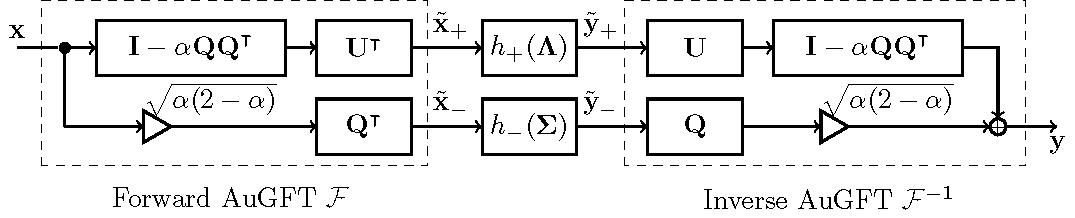

- 
$$0\leq \alpha \leq 1$$


- 
$$\beta = \sqrt{\alpha(2-\alpha)$$


syms alpha beta
eqn1 = alpha == (1-sqrt(1-beta^2));
eqn2 = beta <= 1;
eqn3 = beta >= 0;
eqn4 = alpha <= 1;
eqn5 = alpha >= 0;
eqns = [eqn1; eqn2; eqn3; eqn4; eqn5]

$$eqns = \left(\begin{array}{c} \alpha =1-\sqrt{1-\beta^{2}}\\ \beta \leq 1\\ 0\leq \beta \\ \alpha \leq 1\\ 0\leq \alpha \end{array}\right)$$

res = solve(eqns,beta,'ReturnConditions',true)

res = フィールドをもつ struct :
          beta: [2×1 sym]
    parameters: [1×0 sym]
    conditions: [2×1 sym]


res.beta

$$ans = \left(\begin{array}{c} 0\\ \sqrt{-\alpha \,\left(\alpha -2\right)} \end{array}\right)$$

res.conditions

$$ans = \left(\begin{array}{c} \alpha =0\\ 0<\alpha \wedge \alpha <1 \end{array}\right)$$

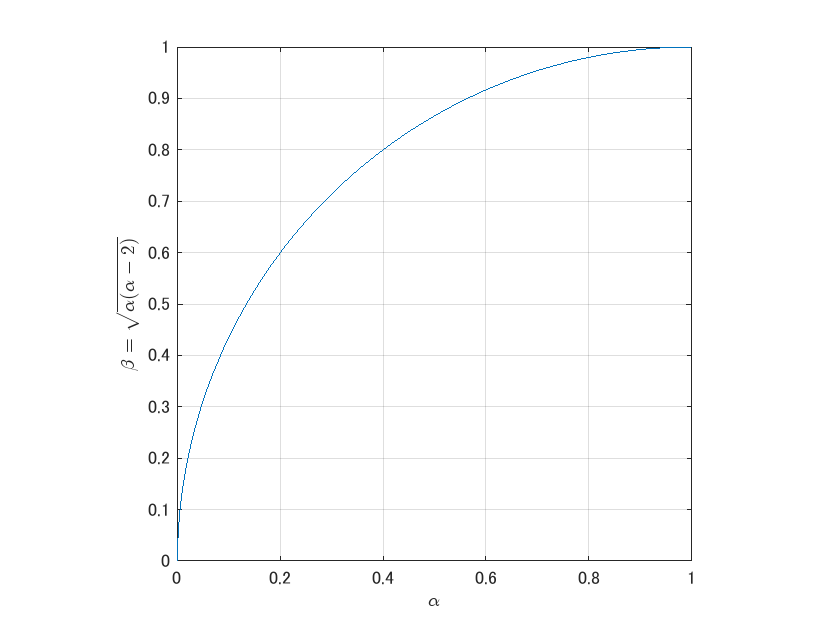

figure
fplot(@(x) sqrt(x.*(2-x)),[0 1])
xlabel('$\alpha$','Interpreter','latex')
ylabel('$\beta=\sqrt{\alpha(\alpha-2)}$','Interpreter','latex')
axis equal
grid on

x = waterlevel;
freqXSet = fcn_fwdAuGFT(x,U,Q)

freqXSet =     0.9042    1.1774   -0.2727    0.3022   -0.1185   -0.2584   -1.4769    0.9601   -0.7312    0.5544
   -1.8557    0.3557    1.3726   -0.8539   -0.2047   -0.8563   -0.6531    0.4731    1.1875   -0.6795
    0.0039    0.0875    0.3302    0.1556   -1.4592   -0.8640   -0.3350    0.2456    0.5336    0.9795
   -0.0642   -0.3141   -0.5781    0.3279    1.1809    2.6051   -0.4101   -0.7243    0.0261   -1.0300
    0.0554   -0.7264   -2.2700   -0.1643   -0.1787    0.9023    0.1539   -0.6440   -1.0555   -0.6250
   -0.2909   -0.1784    1.4559    0.8020    0.7070   -0.3775    0.0883   -0.4681    0.1229    0.0628
   -0.6715   -0.1486    1.4496    0.5723   -0.5182   -1.0226    0.3081    0.6858   -0.5589    0.4761
   -0.8344    0.7398   -0.9108    0.0564   -0.5670    0.7137   -0.4479   -0.5096   -0.3123    0.7105
    1.5896   -0.5973   -0.8099    0.2439   -0.4632    0.6083    1.1294   -0.2500    1.3901   -0.8081
   -1.1049    1.2757    0.1300    0.0390   -0.8860    0.4704    0.5694    1.2209

y = fcn_invAuGFT(freqXSet,U,Q)

y =    -1.3499    0.6715    0.8884   -0.1022   -0.8637   -1.0891   -0.6156    1.4193   -1.1480    0.8404
    3.0349   -1.2075   -1.1471   -0.2414    0.0774    0.0326    0.7481    0.2916    0.1049   -0.8880
    0.7254    0.7172   -1.0689    0.3192   -1.2141    0.5525   -0.1924    0.1978    0.7223    0.1001
   -0.0631    1.6302   -0.8095    0.3129   -1.1135    1.1006    0.8886    1.5877    2.5855   -0.5445
    0.7147    0.4889   -2.9443   -0.8649   -0.0068    1.5442   -0.7648   -0.8045   -0.6669    0.3035
   -0.2050    1.0347    1.4384   -0.0301    1.5326    0.0859   -1.4023    0.6966    0.1873   -0.6003
   -0.1241    0.7269    0.3252   -0.1649   -0.7697   -1.4916   -1.4224    0.8351   -0.0825    0.4900
    1.4897   -0.3034   -0.7549    0.6277    0.3714   -0.7423    0.4882   -0.2437   -1.9330    0.7394
    1.4090    0.2939    1.3703    1.0933   -0.2256   -1.0616   -0.1774    0.2157   -0.4390    1.7119
    1.4172   -0.7873   -1.7115    1.1093    1.1174    2.3505   -0.1961   -1.1658   -1.7

rmse = @(rx,ry) norm(rx(:)-ry(:),2)/sqrt(numel(rx));
rmse(waterlevel,y)

ans = 7.4811e-16

assert(norm(x(:)-y(:))<1e-6)